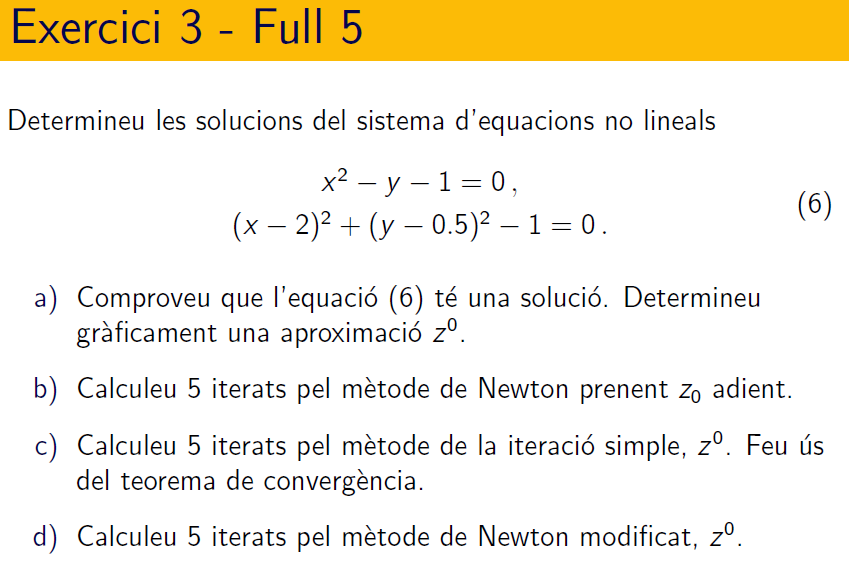

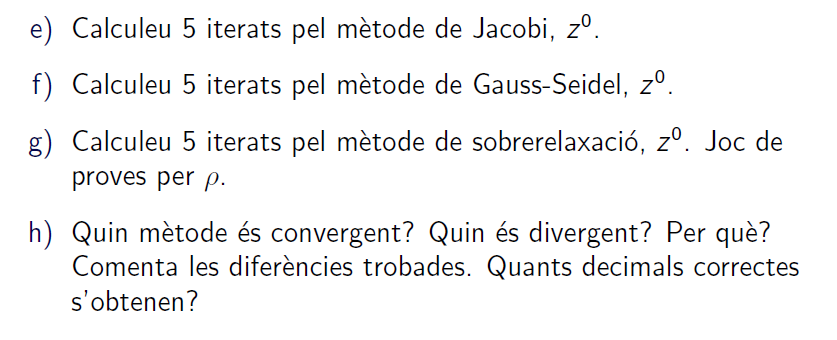

clearvars; format short g;

syms x y
sym_F(x,y) = x.^2 - y - 1;
sym_G(x,y) = (x-2).^2 + (y-0.5)^2 -1;
sym_H(x,y)=[sym_F(x,y); sym_G(x,y)];
sym_JH(x,y)=jacobian(sym_H(x,y),[x,y]);

F = matlabFunction(sym_F);
G = matlabFunction(sym_G);
H = matlabFunction(sym_H);
JH = matlabFunction(sym_JH);

sym_F_itera(x,y) = x.*(x+1) - y - 1;
sym_G_itera(x,y) = (x-2).^2 + y.^2 - 0.75; % (y-0.5)^2 -1 + y --> y.^2 - y + 0.5^2 - 1 + y --> y.^2 + 0.25 - 1
sym_H_itera(x,y) = [sym_F_itera(x,y); sym_G_itera(x,y)];
sym_JH_itera(x,y)=jacobian(sym_H_itera(x,y),[x,y]);

F_itera = matlabFunction(sym_F_itera);
G_itera = matlabFunction(sym_G_itera);
H_itera = matlabFunction(sym_H_itera);
JH_itera = matlabFunction(sym_JH_itera);


tolZ= eps;
tolF= eps; 
Nmax=5;

### APARTADO A

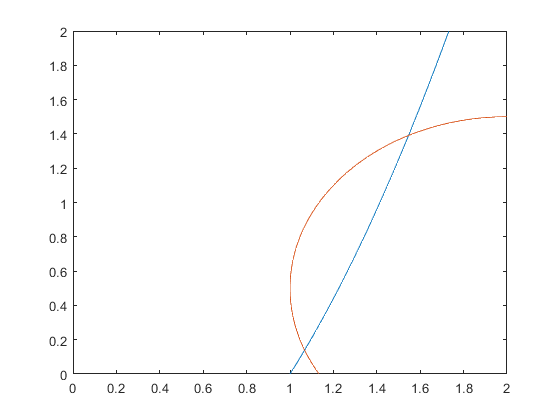

fimplicit({F,G}); xlim([0 2]); ylim([0 2]);

Z0 = [0.1; 1.1];
%Z0 = [1.5; 1.4];

sol = fsolve(@system, Z0')


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


sol =        1.0673      0.13923


### APARTADO B (NEWTON)

alpha = zeros(Nmax,2);

for k = 1:Nmax
    alpha(k,:) = newton2d(H,JH,Z0,k,tolF,tolZ);
    if k > 1 && alpha(k,1) == alpha(k-1,1) && alpha(k,2) == alpha(k-1,2) break; end
end


solución = 0.22978    -0.96404
tolF = 4.2772
tolZ = 2.0681
iteraciones = 1


solución = 1.0951    -0.54956
tolF = 1.1865
tolZ = 0.95943
iteraciones = 2


solución = 0.99343   -0.023422
tolF = 0.28734
tolZ = 0.53587
iteraciones = 3


solución = 1.0609     0.12105
tolF = 0.025835
tolZ = 0.15947
iteraciones = 4


solución = 1.0672     0.13898
tolF = 0.00036349
tolZ = 0.019008
iteraciones = 5



#### Analisis del apartado H:

array2table(alpha(1:k,:), "VariableNames", {'x', 'y'}), delta = min(abs(sol - alpha(k,:)))

ans = 5×2 table
       x           y    
    _______    _________

    0.22978     -0.96404
     1.0951     -0.54956
    0.99343    -0.023422
     1.0609      0.12105
     1.0672      0.13898


delta =    9.7617e-05


El metodo es convergente  y obtiene 4 decimales correctos.

### APARTADO C (ITER)

control=JH_itera(Z0(1),Z0(2));
control2=norm(control,1);
criteriTEOREMA=vpa(control2,8);

if criteriTEOREMA >=1 
    disp('método divergente')
else
    disp('método convergente')

    alpha = zeros(Nmax,2);
    for k = 1:Nmax
        alpha(k,:) = itera2d(H_itera,H,Z0,k,0.5*10^(-7));
        if k > 1 && alpha(k,1) == alpha(k-1,1) && alpha(k,2) == alpha(k-1,2) break; end
    end
    

#### Analisis del apartado H:

    array2table(alpha(1:k,:), "VariableNames", {'x', 'y'}), delta = min(abs(sol - alpha(k,:)))
end

método divergente


### APARTADO D (NEWTON MOD)

alpha = zeros(Nmax,2);
for k = 1:Nmax
    alpha(k,:) = newton2dMOD(H,JH,Z0,k,tolF,tolZ,3);
    if k > 1 && alpha(k,1) == alpha(k-1,1) && alpha(k,2) == alpha(k-1,2) break; end
end

#### Analisis del apartado H:

array2table(alpha(1:k,:), "VariableNames", {'x', 'y'}), delta = min(abs(sol - alpha(k,:)))

ans = 5×2 table
       x          y    
    _______    ________

    0.22978    -0.96404
     1.4369    -0.70578
     2.2502      1.2273
     1.7227      1.6896
     1.5955      1.3952


delta =       0.52815


El metodo es aparentemente convergente, pero no podemos asegurarlo, porque necesitamos mas iteraciones para dar una respuesta clara. No obtiene decimales correctos.

### APARTADO E (JAC)

alpha = zeros(Nmax,2);
for k = 1:Nmax
    alpha(k,:) = newton2dJACOBI(H,JH,Z0,k,tolF,tolZ);
    if k > 1 && alpha(k,1) == alpha(k-1,1) && alpha(k,2) == alpha(k-1,2) break; end
end

#### Analisis del apartado H:

array2table(alpha(1:k,:), "VariableNames", {'x', 'y'}), delta = min(abs(sol - alpha(k,:)))

ans = 5×2 table
      x         y   
    ______    ______

     10.55    -1.375
    5.2572     18.79
    4.5108    9.3822
    3.4062    4.6425
    2.5314    2.4533


delta =         1.464


No es convergente, y no obtiene ningun decimal correcto.

### APARTADO F (GS)

alpha = zeros(Nmax,2);
for k = 1:Nmax
    alpha(k,:) = newton2dGS(H,JH,Z0,k,tolF,tolZ);
    if k > 1 && alpha(k,1) == alpha(k-1,1) && alpha(k,2) == alpha(k-1,2) break; end
end

#### Analisis del apartado H:

array2table(alpha(1:k,:), "VariableNames", {'x', 'y'}), delta = min(abs(sol - alpha(k,:)))

ans = 5×2 table
      x         y   
    ______    ______

     10.55    31.717
    6.8256    15.974
    4.6562    8.1932
    3.3153     4.416
    2.4745    2.6472


delta =        1.4071


No es convergente, y no obtiene decimales correctos.

### APARTADO G (SOR)


for w = 0.1:0.1:1.9 % 0 < w < 2
    rho = 1/w - 1;

    alpha = zeros(Nmax,2);
    for k = 1:Nmax
        alpha(k,:) = newton2dSOR(H,JH,Z0,k,tolF,tolZ,rho);
        if k > 1 && alpha(k,1) == alpha(k-1,1) && alpha(k,2) == alpha(k-1,2) break; end
    end
    

#### Analisis del apartado H:

    rho, array2table(alpha(1:k,:), "VariableNames", {'x', 'y'}), delta = min(abs(sol - alpha(k,:)))
end

rho =      9


ans = 5×2 table
      x         y   
    ______    ______

     1.145    1.1834
    1.1831    1.1737
    1.2158    1.1687
    1.2442    1.1674
    1.2691    1.1689


delta =       0.20174


rho =      4


ans = 5×2 table
      x         y   
    ______    ______

      2.19    1.9287
    2.1047    1.8555
    2.0299    1.7941
    1.9646    1.7422
    1.9077    1.6981


delta =       0.84036


rho =        2.3333


ans = 5×2 table
      x         y   
    ______    ______

     3.235    3.3357
    2.9508    2.9197
    2.7074    2.5914
    2.5003    2.3346
    2.3253     2.135


delta =        1.2579


rho =           1.5


ans = 5×2 table
      x         y   
    ______    ______

      4.28    5.4047
    3.7233    4.3561
    3.2663    3.5644
    2.8925    2.9739
    2.5888    2.5394


delta =        1.5215


rho =      1


ans = 5×2 table
      x         y   
    ______    ______

     5.325    8.1354
    4.4226    6.0938
     3.718    4.6303
    3.1671    3.5942
     2.738    2.8723


delta =        1.6706


rho =       0.66667


ans = 5×2 table
      x         y   
    ______    ______

      6.37    11.528
     5.049    8.0414
    4.0715     5.686
    3.3427    4.1145
    2.7989    3.0847


delta =        1.7316


rho =       0.42857


ans = 5×2 table
      x         y   
    ______    ______

     7.415    15.582
    5.6025    10.102
    4.3352    6.6374
    3.4345    4.4753
    2.7904    3.1535


delta =         1.723


rho =          0.25


ans = 5×2 table
      x         y   
    ______    ______

      8.46    20.299
     6.083    12.177
    4.5163    7.4075
    3.4544    4.6452
    2.7263    3.0839


delta =         1.659


rho =       0.11111


ans = 5×2 table
      x         y   
    ______    ______

     9.505    25.677
    6.4907    14.167
    4.6214    7.9386
    3.4122    4.6195
    2.6178    2.9022


delta =        1.5505


rho =      0


ans = 5×2 table
      x         y   
    ______    ______

     10.55    31.717
    6.8256    15.974
    4.6562    8.1932
    3.3153     4.416
    2.4745    2.6472


delta =        1.4071


rho =     -0.090909


ans = 5×2 table
      x         y   
    ______    ______

    11.595    38.418
    7.0875    17.497
    4.6248    8.1544
    3.1698    4.0701
    2.3061    2.3611


delta =        1.2388


rho =      -0.16667


ans = 5×2 table
      x         y   
    ______    ______

     12.64    45.782
    7.2767    18.638
    4.5299    7.8262
     2.981    3.6301
    2.1243    2.0814


delta =         1.057


rho =      -0.23077


ans = 5×2 table
      x         y   
    ______    ______

    13.685    53.807
     7.393    19.298
    4.3722    7.2348
    2.7545    3.1513
    1.9437    1.8335


delta =       0.87634


rho =      -0.28571


ans = 5×2 table
      x         y   
    ______    ______

     14.73    62.495
    7.4364    19.377
     4.149    6.4296
    2.4982    2.6893
    1.7832    1.6249


delta =       0.71588


rho =      -0.33333


ans = 5×2 table
      x         y   
    ______    ______

    15.775    71.844
     7.407    18.775
    3.8541    5.4868
    2.2258    2.2882
    1.6644    1.4514


delta =       0.59706


rho =        -0.375


ans = 5×2 table
      x         y   
    ______    ______

     16.82    81.855
    7.3048    17.394
    3.4755    4.5175
    1.9651    1.9566
    1.5967    1.3258


delta =       0.52931


rho =      -0.41176


ans = 5×2 table
      x         y   
    ______    ______

    17.865    92.527
    7.1297    15.135
     2.993    3.6899
    1.7809    1.6237
    1.5194     1.302


delta =       0.45207


rho =      -0.44444


ans = 5×2 table
      x         y   
    ______    ______

     18.91    103.86
    6.8818    11.897
    2.3749    3.3116
    1.8714    1.1771
    1.2341    1.6571


delta =       0.16679


rho =      -0.47368


ans = 5×2 table
       x         y   
    _______    ______

     19.955    115.86
      6.561    7.5822
     1.5707     4.304
     3.2865    1.2618
    0.81812    7.6414


delta =       0.24922


El metodo parece convergente, pero de forma lenta. Obtiene un decimal correcto en el mejor de los casos. Probablemente 5 iteraciones no sean suficientes.

function F=system(Z0)
    syms x y
    sym_F(x,y) = x.^2 - y - 1;
    sym_G(x,y) = (x-2).^2 + (y-0.5)^2 -1;
    sym_H(x,y)=[sym_F(x,y); sym_G(x,y)];
    H = matlabFunction(sym_H);

    F = H(Z0(1),Z0(2));
end